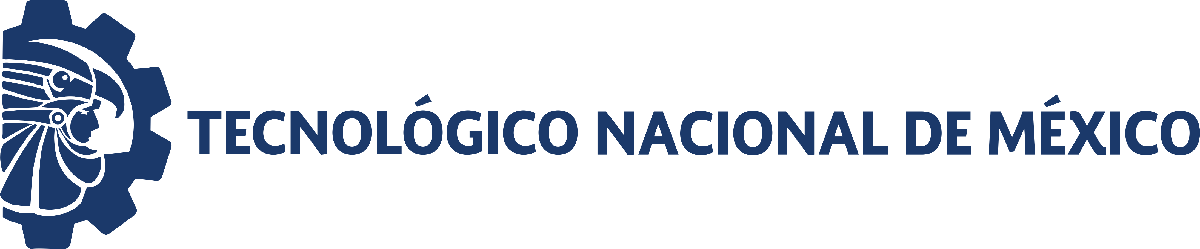                                 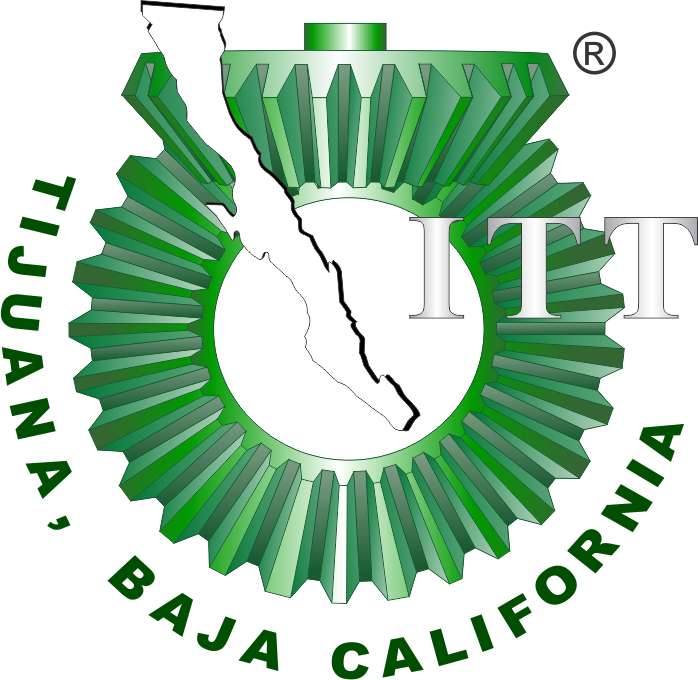

# Práctica 3: Liberación controlada de fármacos por hidrogeles

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

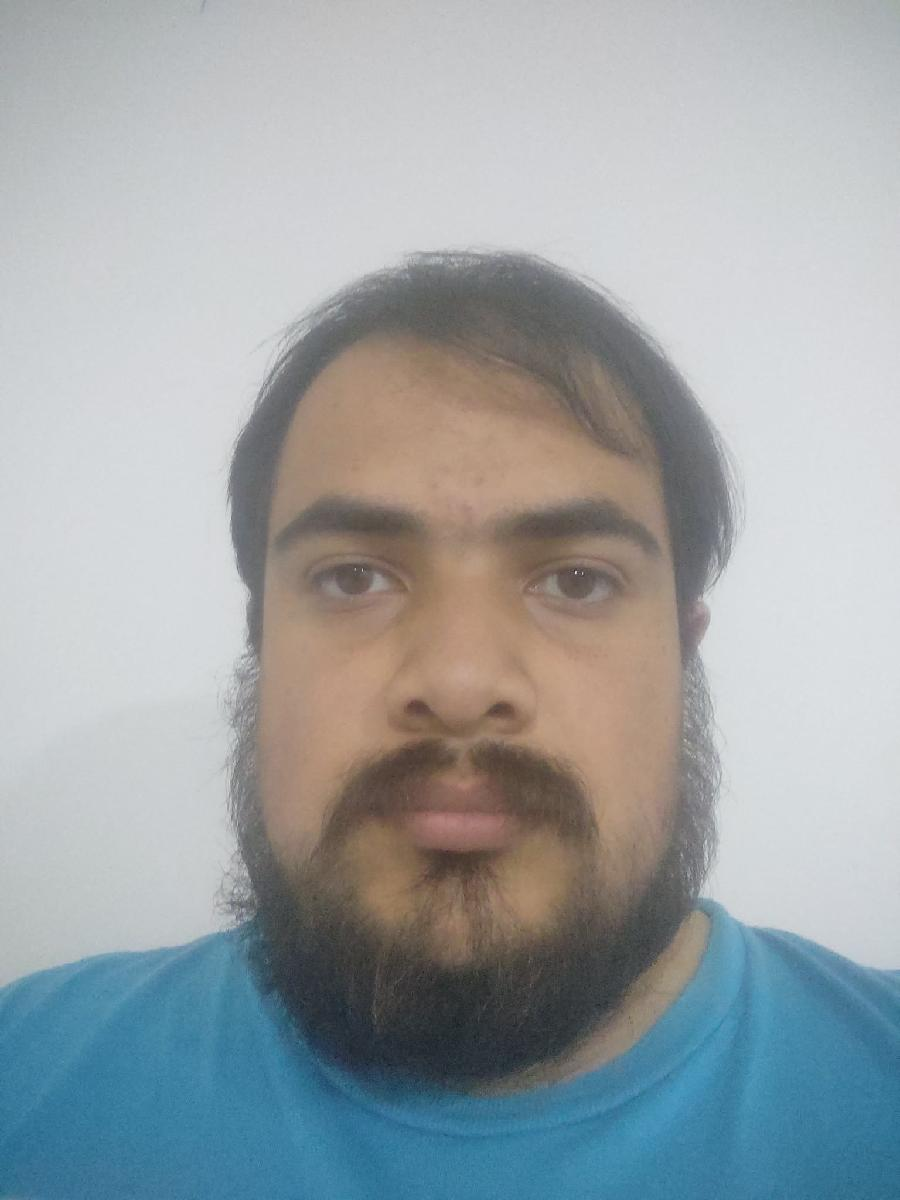

Nombre del alumno: **Oscar González Ramírez**

Número de control: **M25210050**

Correo institucional: **m25210050@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Objetivo

Determinar la tasa de liberación del hidrogel N36 2MBA3 con base en los datos experimentales de la siguiente figura.

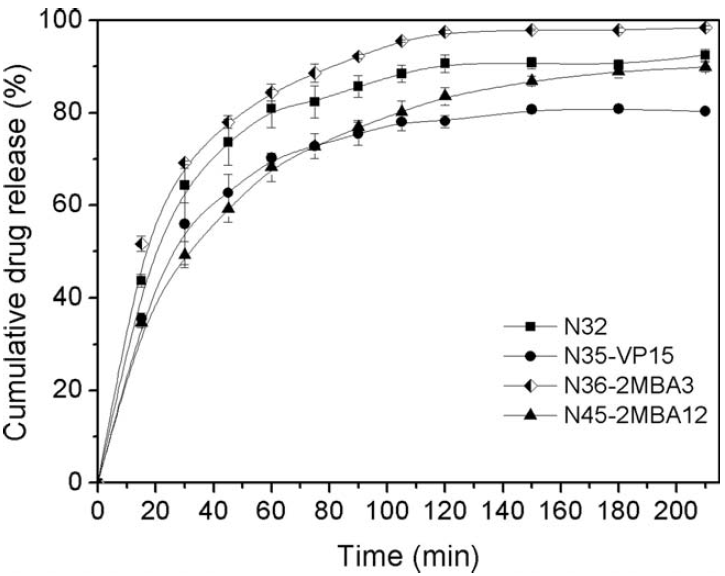

## Referencia

M. A. González‐Ayón, J.A. Sañudo‐Barajas, L.A. Picos‐Corrales, & A. Licea‐Claverie, "PNVCL‐PEGMA nanohydrogels with tailored transition temperature for controlled delivery of 5‐fluorouracil", *Journal of Polymer Science Part A: Polymer Chemistry*, vol. 53, issue 22, pp. 2662-2672, Aug 2015. DOI: [https://doi.org/10.1002/pola.27766](https://doi.org/10.1002/pola.27766)

## Modelos a ajustar a los datos experimentales

Ecuación de Peppas: $x\left(t\right)=kt^n$

Farmacocinética de primer orden: $$x(t) = \beta(1 - e^{-kt})$ $

Eureqa: $$x(t) = \frac{t}{\rho_1+t\rho_2}$ $

Eureqa EDO: $\dot{x} =\rho_1 -\rho_2 x_1$

## Datos experimentales

     t      N45       N32       N35       N36  
    ___    ______    ______    ______    ______

      0         0         0         0         0
     15    34.776     43.78     35.57    51.726
     30     49.21    64.439    56.073    69.338
     45    59.406    73.841    62.717    78.078
     60    68.544    81.124    70.398    84.435
     75    72.914    82.581    72.914    88.672
     90    77.019    85.891    75.562     92.38
    105    80.462    88.672    78.138    95.691
    120    83.773    90.791    78.343    97.545
    150    86.951    91.056    80.859    98.074
    180    89.202    90.526    80.992    97.942
    210    90.129    92.513    80.329    98.472



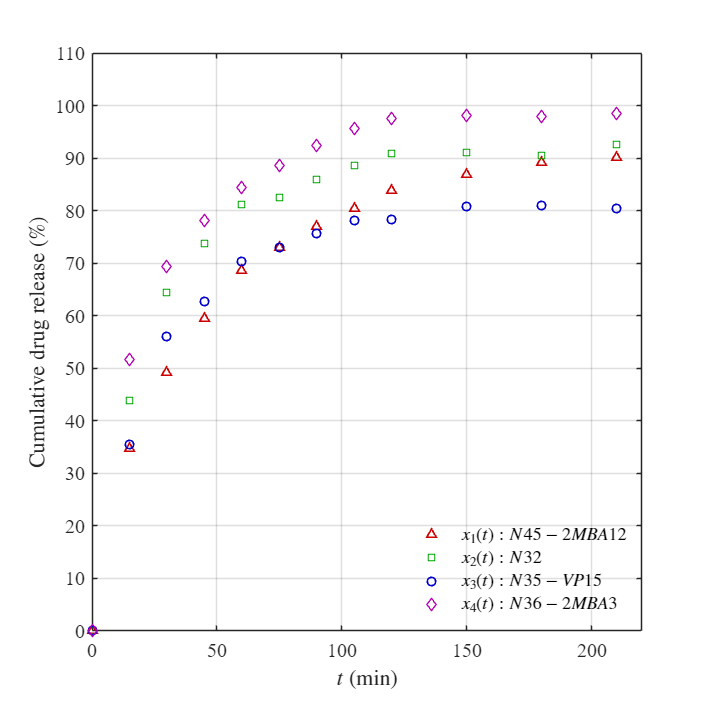

clc; clear; close all; warning('off')
[t, x1, x2, x3, x4] = getdata('data.csv'); 
plotdata(t, x1, x2, x3, x4); exportgraphics(gcf, 'data.pdf','ContentType','vector')

## Regresión no lineal, bioestadísticos y experimentación in silico

labels = {'x1(t):N45-2MBA12','x2(t):N32','x3(t):N35-VP15','x4(t):N36-NMBA3'};
xo = [x1,x2,x3,x4]; s = size(xo);

### Función de Peppas

n0 = 0.1; k0 = 0.1; xp = zeros(s(1),s(2));
for i = 1:4
    disp(['Resultados para el Hidrogel: ', string(labels(i))]);
    mdl = peppas(t, xo(:,i), [n0;k0]);
    xp(:,i) = mdl.Fitted; disp(' ');
end

    "Resultados para el Hidrogel: "    "x1(t):N45-2MBA12"



Cantidad de datos: 12
Cantidad de paramétros 2
Grados de libertad: 10
Valor de t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}        17.752       2.1679      4.8304     12.922     22.582    9.5966e-06
      {'n'}       0.31622     0.026015    0.057964    0.25826    0.37419    2.5878e-07

R-cuadrada ordinaria: 0.98005
Suma residual de cuadrados: 157.9402
Criterio de Información de Akaike ajustado: 70.3156

    "Resultados para el Hidrogel: "    "x2(t):N32"



Cantidad de datos: 12
Cantidad de paramétros 2
Grados de libertad: 10
Valor de t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}        30.676       4.3225      9.6312     21.045     40.307    3.3083e-05
      {'n'}       0.21899     0.030498    0.067953    0.15103    0.28694     2.995e-05

R-cuadrada ordinaria: 0.96289
Suma residual de cuadrados: 302.3979
Criterio de Información de Akaike ajustado: 78.1099

    "Resultados para el Hidrogel: "    "x3(t):N35-VP15"



Cantidad de datos: 12
Cantidad de paramétros 2
Grados de libertad: 10
Valor de t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}        24.864       3.8819      8.6493     16.215     33.514      7.78e-05
      {'n'}       0.23538     0.033694    0.075074    0.16031    0.31045    3.7793e-05

R-cuadrada ordinaria: 0.95739
Suma residual de cuadrados: 275.5506
Criterio de Información de Akaike ajustado: 76.9942

    "Resultados para el Hidrogel: "    "x4(t):N36-NMBA3"



Cantidad de datos: 12
Cantidad de paramétros 2
Grados de libertad: 10
Valor de t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}        34.384       3.8594      8.5992     25.785     42.983    4.5324e-06
      {'n'}       0.20974     0.024333    0.054218    0.15553    0.26396    6.0909e-06

R-cuadrada ordinaria: 0.97528
Suma residual de cuadrados: 225.0748
Criterio de Información de Akaike ajustado: 74.5662

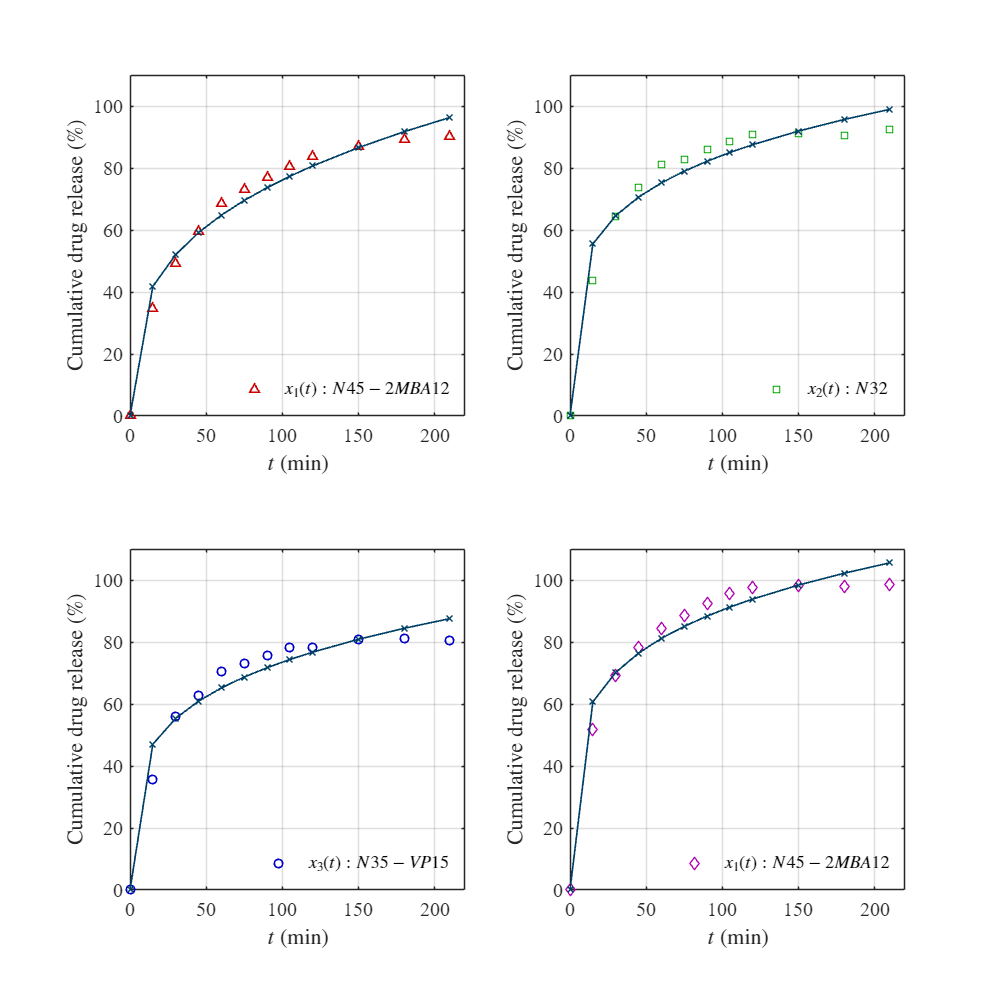

plotresults(t,xo,xp); exportgraphics(gcf, 'peppas.pdf','ContentType','vector')

### **Función farmacocinética de primer orden**

beta = 100; k0 = 0.01; xp = zeros(s(1),s(2));
for i = 1:4
    disp(['Resultados para el Hidrogel: ', string(labels(i))]);
    mdl = farmacocinetica(t, xo(:,i), [beta;k0]);
    xp(:,i) = mdl.Fitted; disp(' ');
end

    "Resultados para el Hidrogel: "    "x1(t):N45-2MBA12"



Cantidad de datos: 12
Cantidad de paramétros 2
Grados de libertad: 10
Valor de t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE          MoE               CI95              Pvalue  
    __________    ________    ________    _________    ____________________    __________

      {'k'}         87.985      1.4828       3.3039      84.681      91.289    4.4904e-14
      {'n'}       0.026018    0.001548    0.0034491    0.022569    0.029467     1.166e-08

R-cuadrada ordinaria: 0.99085
Suma residual de cuadrados: 72.4623
Criterio de Información de Akaike ajustado: 60.9658

    "Resultados para el Hidrogel: "    "x2(t):N32"



Cantidad de datos: 12
Cantidad de paramétros 2
Grados de libertad: 10
Valor de t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

      {'k'}         90.118      0.80499       1.7936      88.324      91.912    7.9306e-17
      {'n'}       0.040475    0.0017021    0.0037926    0.036682    0.044267    3.9292e-10

R-cuadrada ordinaria: 0.9956
Suma residual de cuadrados: 35.8524
Criterio de Información de Akaike ajustado: 52.5219

    "Resultados para el Hidrogel: "    "x3(t):N35-VP15"



Cantidad de datos: 12
Cantidad de paramétros 2
Grados de libertad: 10
Valor de t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

      {'k'}          79.64      0.67076       1.4945      78.146      81.135    4.4057e-17
      {'n'}       0.037402    0.0014096    0.0031408    0.034261    0.040543    1.3337e-10

R-cuadrada ordinaria: 0.99643
Suma residual de cuadrados: 23.1021
Criterio de Información de Akaike ajustado: 47.248

    "Resultados para el Hidrogel: "    "x4(t):N36-NMBA3"



Cantidad de datos: 12
Cantidad de paramétros 2
Grados de libertad: 10
Valor de t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

      {'k'}         96.243       1.3614       3.0334       93.21      99.276    7.8221e-15
      {'n'}       0.042079    0.0028729    0.0064013    0.035678     0.04848    4.3954e-08

R-cuadrada ordinaria: 0.98834
Suma residual de cuadrados: 106.1131
Criterio de Información de Akaike ajustado: 65.543

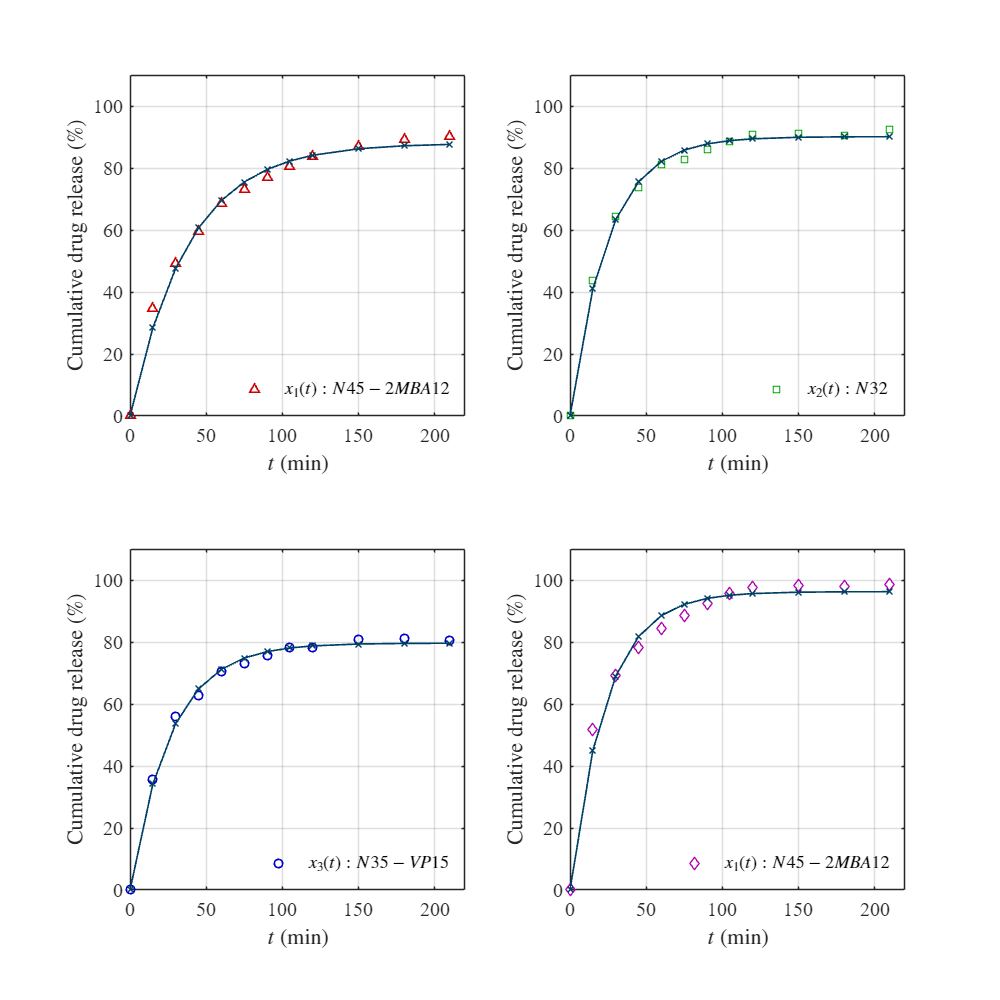

plotresults(t,xo,xp); exportgraphics(gcf, 'farmacocinetica.pdf','ContentType','vector')

### Eureqa: función en el tiempo

% Función utilizada: x1 = t./(rho1 + t.*rho2)
% índice fit: 0.035
rho1 = 0.319; rho2 = 0.00944; xp = zeros(s(1),s(2));
for i = 1:4
    disp(['Resultados para el Hidrogel: ', string(labels(i))]);
    mdl = eureqafunction(t, xo(:,i), [rho1;rho2]);
    xp(:,i) = mdl.Fitted; disp(' ');
end

    "Resultados para el Hidrogel: "    "x1(t):N45-2MBA12"



Cantidad de datos: 12
Cantidad de paramétros 2
Grados de libertad: 10
Valor de t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate         SE           MoE                 CI95               Pvalue  
    __________    _________    __________    __________    ______________________    __________

     {'rho1'}       0.31213     0.0080087      0.017844      0.29428      0.32997    2.9533e-12
     {'rho2'}     0.0094933    8.9301e-05    0.00019897    0.0092944    0.0096923    1.3295e-16

R-cuadrada ordinaria: 0.99884
Suma residual de cuadrados: 9.2098
Criterio de Información de Akaike ajustado: 36.2122

    "Resultados para el Hidrogel: "    "x2(t):N32"



Cantidad de datos: 12
Cantidad de paramétros 2
Grados de libertad: 10
Valor de t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate         SE           MoE                 CI95               Pvalue  
    __________    _________    __________    __________    ______________________    __________

     {'rho1'}       0.17537     0.0090374      0.020136      0.15523       0.1955    2.8833e-09
     {'rho2'}     0.0097695    0.00012135    0.00027039    0.0094991      0.01004    2.1369e-15

R-cuadrada ordinaria: 0.99647
Suma residual de cuadrados: 28.7788
Criterio de Información de Akaike ajustado: 49.8846

    "Resultados para el Hidrogel: "    "x3(t):N35-VP15"



Cantidad de datos: 12
Cantidad de paramétros 2
Grados de libertad: 10
Valor de t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE           MoE              CI95             Pvalue  
    __________    ________    _________    _________    __________________    __________

     {'rho1'}      0.2204       0.01316     0.029323    0.19107    0.24972    1.2076e-08
     {'rho2'}     0.01095     0.0001705    0.0003799    0.01057    0.01133    2.0393e-14

R-cuadrada ordinaria: 0.99499
Suma residual de cuadrados: 32.4049
Criterio de Información de Akaike ajustado: 51.3087

    "Resultados para el Hidrogel: "    "x4(t):N36-NMBA3"



Cantidad de datos: 12
Cantidad de paramétros 2
Grados de libertad: 10
Valor de t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate         SE           MoE                 CI95               Pvalue  
    __________    _________    __________    __________    ______________________    __________

     {'rho1'}       0.15341      0.006018      0.013409      0.14001      0.16682    1.9796e-10
     {'rho2'}     0.0092141    8.2728e-05    0.00018433    0.0090297    0.0093984    8.3471e-17

R-cuadrada ordinaria: 0.99802
Suma residual de cuadrados: 18.0415
Criterio de Información de Akaike ajustado: 44.2811

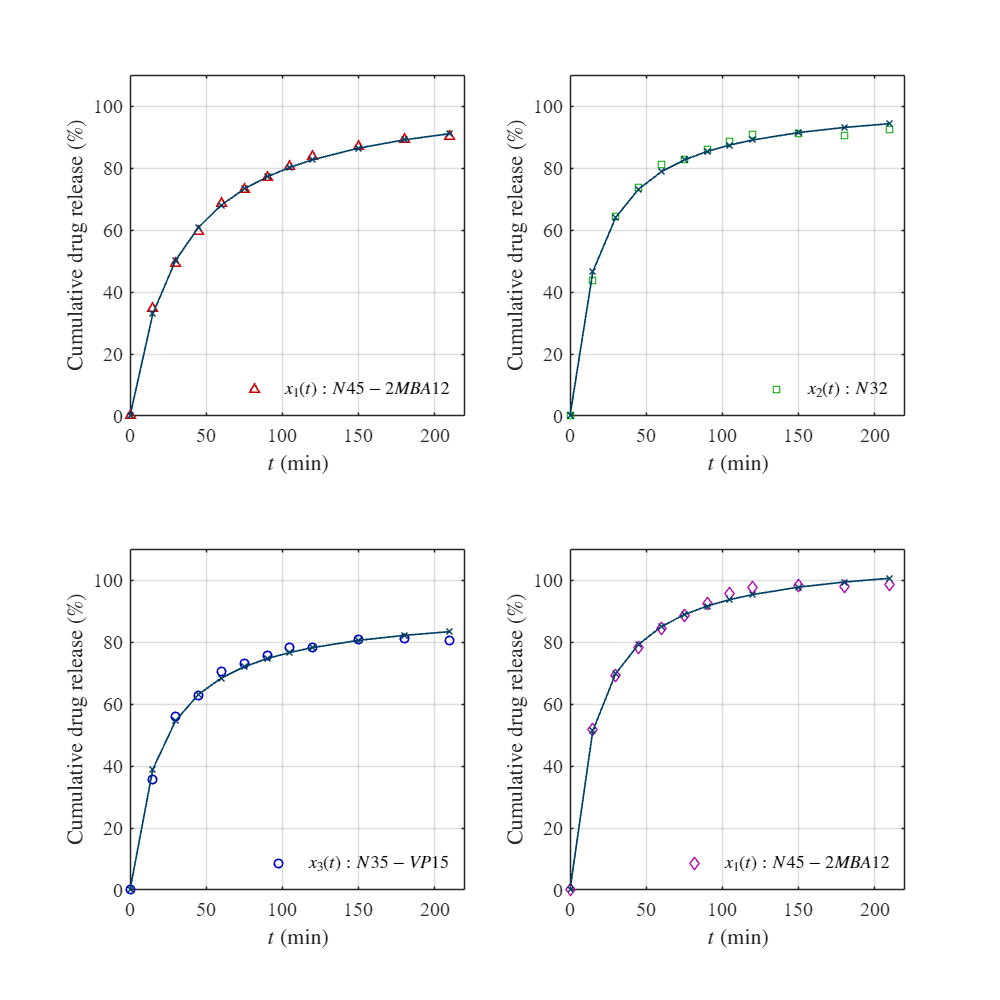

plotresults(t,xo,xp); exportgraphics(gcf, 'eureqafunction.pdf','ContentType','vector')

### Eureqa: farmacocinética de primer orden

rho1 = 2.29; rho2 = 0.0258; xp = zeros(s(1),s(2));
for i = 1:4
    disp(['Resultados para el Hidrogel: ', string(labels(i))]);
    mdl = eureqaODE(t, xo(:,i), [rho1;rho2]);
    xp(:,i) = mdl.Fitted; disp(' ');
end

    "Resultados para el Hidrogel: "    "x1(t):N45-2MBA12"



Cantidad de datos: 12
Cantidad de paramétros 2
Grados de libertad: 10
Valor de t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'rho1'}       2.2893      0.10981      0.24466      2.0446      2.5339    1.4293e-09
     {'rho2'}     0.026019    0.0015476    0.0034483    0.022571    0.029467    1.1631e-08

R-cuadrada ordinaria: 0.99085
Suma residual de cuadrados: 72.4319
Criterio de Información de Akaike ajustado: 60.9607

    "Resultados para el Hidrogel: "    "x2(t):N32"



Cantidad de datos: 12
Cantidad de paramétros 2
Grados de libertad: 10
Valor de t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE          MoE               CI95              Pvalue  
    __________    ________    _________    ________    ____________________    __________

     {'rho1'}       3.6468      0.13538     0.30165      3.3451      3.9484    1.1493e-10
     {'rho2'}     0.040466    0.0017005    0.003789    0.036677    0.044254    3.9009e-10

R-cuadrada ordinaria: 0.9956
Suma residual de cuadrados: 35.8186
Criterio de Información de Akaike ajustado: 52.5106

    "Resultados para el Hidrogel: "    "x3(t):N35-VP15"



Cantidad de datos: 12
Cantidad de paramétros 2
Grados de libertad: 10
Valor de t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'rho1'}       2.9784     0.097731      0.21776      2.7606      3.1961    3.3909e-11
     {'rho2'}     0.037397    0.0014072    0.0031355    0.034262    0.040533    1.3133e-10

R-cuadrada ordinaria: 0.99644
Suma residual de cuadrados: 23.0493
Criterio de Información de Akaike ajustado: 47.2206

    "Resultados para el Hidrogel: "    "x4(t):N36-NMBA3"



Cantidad de datos: 12
Cantidad de paramétros 2
Grados de libertad: 10
Valor de t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'rho1'}       4.0486      0.24569      0.54744      3.5012       4.596    1.4124e-08
     {'rho2'}     0.042065    0.0028725    0.0064004    0.035664    0.048465    4.4033e-08

R-cuadrada ordinaria: 0.98835
Suma residual de cuadrados: 106.0979
Criterio de Información de Akaike ajustado: 65.5413

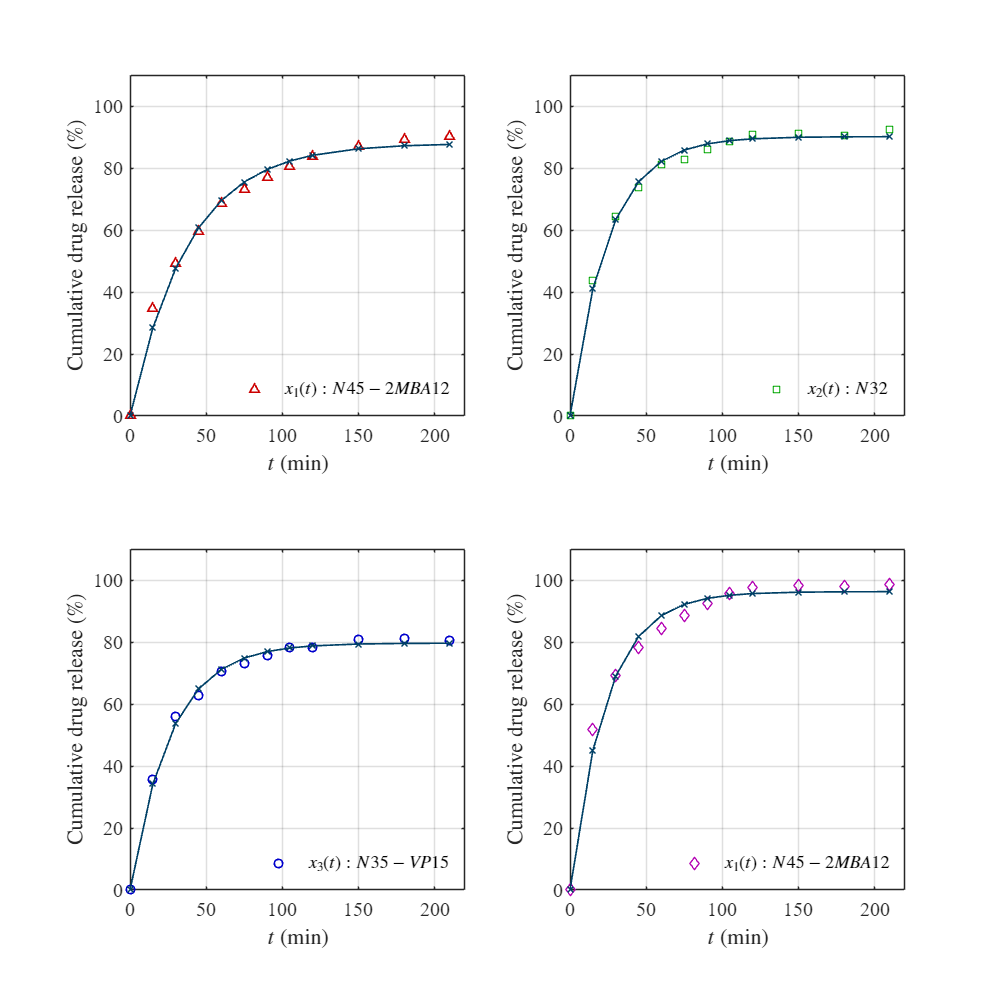

plotresults(t,xo,xp); exportgraphics(gcf, 'eureqaode.pdf','ContentType','vector')

## Funciones

### Datos experimentales

function [t, a, b, c, d] = getdata(file)
    sys = readmatrix(file);
    t = round(sys(:,1));
    a = sys(:,2);
    b = sys(:,3);
    c = sys(:,4);
    d = sys(:,5);
end

function plotdata(t,x1,x2,x3,x4)
    N45 = x1; N32 = x2; N35 = x3; N36 = x4;
    disp(table(t,N45,N32,N35,N36));
    set(figure(),'Color','w')
    FS = 12;
    set(gcf,'Units','Centimeters','Position',[1,1,15,15])
    hold on;
    plot(t,x1,'^','LineWidth',1,'MarkerSize',5,'Color',[0.8,0,0])
    hold on;
    plot(t,x2,'square','LineWidth',1,'MarkerSize',5,'Color',[0,0.65,0])
    hold on;
    plot(t,x3,'o','LineWidth',1,'MarkerSize',5,'Color',[0,0,0.8])
    hold on;
    plot(t,x4,'diamond', 'LineWidth',1,'MarkerSize',5,'Color',[0.7,0,0.7])
    axis([0 220 0 110])
    xlabel('$t$ (min)','Interpreter','Latex','FontSize',FS)
    ylabel('Cumulative drug release $(\%)$','Interpreter','latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    L = legend('$x_1(t): N45-2MBA12$','$x_2(t): N32$','$x_3(t): N35-VP15$','$x_4(t): N36-2MBA3$');
    set(L,'Interpreter','Latex','Location','Southeast','Orientation','Horizontal','Box','Off','NumColumns',1)
    box on; grid on;
end

function plotresults(t,xo,xp)
set(figure(),'Color','w')
    FS = 12;
    set(gcf,'Units','Centimeters','Position',[1,1,25,25])
    subplot(2,2,1)
    hold on; box on; grid on;
    plot(t,xo(:,1),'^','LineWidth',1,'MarkerSize',5,'Color',[0.8,0,0])
    hold on;
    plot(t,xp(:,1),'-x','LineWidth',1,'MarkerSize',5,'Color',[0,0.25,0.4])
    axis([0 220 0 110])
    xlabel('$t$ (min)','Interpreter','Latex','FontSize',FS)
    ylabel('Cumulative drug release $(\%)$','Interpreter','latex','FontSize',FS)
    L = legend('$x_1(t): N45-2MBA12$');
    set(L,'Interpreter','Latex','Location','Southeast','Orientation','Horizontal','Box','Off','NumColumns',1)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    subplot(2,2,2)
    hold on; box on; grid on;
    plot(t,xo(:,2),'square','LineWidth',1,'MarkerSize',5,'Color',[0,0.65,0])
    hold on;
    plot(t,xp(:,2),'-x','LineWidth',1,'MarkerSize',5,'Color',[0,0.25,0.4])
    axis([0 220 0 110])
    xlabel('$t$ (min)','Interpreter','Latex','FontSize',FS)
    ylabel('Cumulative drug release $(\%)$','Interpreter','latex','FontSize',FS)
    L = legend('$x_2(t): N32$');
    set(L,'Interpreter','Latex','Location','Southeast','Orientation','Horizontal','Box','Off','NumColumns',1)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    subplot(2,2,3)
    hold on; box on; grid on;
    plot(t,xo(:,3),'o','LineWidth',1,'MarkerSize',5,'Color',[0,0,0.8])
    hold on;
    plot(t,xp(:,3),'-x','LineWidth',1,'MarkerSize',5,'Color',[0,0.25,0.4])
    axis([0 220 0 110])
    xlabel('$t$ (min)','Interpreter','Latex','FontSize',FS)
    ylabel('Cumulative drug release $(\%)$','Interpreter','latex','FontSize',FS)
    L = legend('$x_3(t): N35-VP15$');
    set(L,'Interpreter','Latex','Location','Southeast','Orientation','Horizontal','Box','Off','NumColumns',1)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    subplot(2,2,4)
    hold on; box on; grid on;
    plot(t,xo(:,4),'diamond','LineWidth',1,'MarkerSize',5,'Color',[0.7,0,0.7])
    hold on;
    plot(t,xp(:,4),'-x','LineWidth',1,'MarkerSize',5,'Color',[0,0.25,0.4])
    axis([0 220 0 110])
    xlabel('$t$ (min)','Interpreter','Latex','FontSize',FS)
    ylabel('Cumulative drug release $(\%)$','Interpreter','latex','FontSize',FS)
    L = legend('$x_1(t): N45-2MBA12$');
    set(L,'Interpreter','Latex','Location','Southeast','Orientation','Horizontal','Box','Off','NumColumns',1)
    set(gca,'FontName','Times New Roman','FontSize',FS)
end


### Modelos matemáticos y bioestadísticos

function mdl = peppas(to, xo, par)
    function x = model(par, t)
        k = par(1); n = par(2);
        x = k*t.^n;
    end

    mdl = fitnlm(to,xo,@model,par);
    Parameters = {'k';'n'};
    biostats(mdl, Parameters);
end

function mdl = farmacocinetica(to, xo, par)
    function x = model(par, t)
        beta = par(1); k = par(2);
        x = beta*(1-exp(-k*t));
    end

    mdl = fitnlm(to,xo,@model,par);
    Parameters = {'k';'n'};
    biostats(mdl, Parameters);
end

function mdl = eureqafunction(to, xo, par)
    function x = model(par, t)
        rho1 = par(1); rho2 = par(2);
        x = t./(rho1 + t.*rho2);
    end

    mdl = fitnlm(to,xo,@model,par);
    Parameters = {'rho1';'rho2'};
    biostats(mdl, Parameters);
end


function mdl = eureqaODE(to, xo, par)
    function x = model(par, t)
        rho1 = par(1);
        rho2 = par(2);
        x0 = xo(1); % x1
        f = @(t, x) rho1 - rho2*x;
        [~, x_sol] = ode45(f,t,x0);
        x = x_sol;
    end

    mdl = fitnlm(to, xo, @model, par);
    Parameters = {'rho1'; 'rho2'};
    biostats(mdl, Parameters);
end

function biostats(mdl, Parameters)
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    Pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Results = table(Parameters,Estimate,SE,MoE,CI95,Pvalue);
    disp(['Cantidad de datos: ', num2str(mdl.NumObservations)])
    disp(['Cantidad de paramétros ',num2str(length(Parameters))])
    disp(['Grados de libertad: ',num2str(dof)])
    disp(['Valor de t-student: ',num2str(tval)])
    disp(['Alpha: ',num2str(alpha)])
    disp(' '); disp(Results)
    R2o = mdl.Rsquared.Ordinary;
    SSE = mdl.SSE;
    AICc = mdl.ModelCriterion.AICc;
    fprintf(['R-cuadrada ordinaria: ',num2str(R2o)]);
    fprintf(['\nSuma residual de cuadrados: ',num2str(SSE)]); 
    fprintf(['\nCriterio de Información de Akaike ajustado: ',num2str(AICc)]);
end